# Transformada de Fourier de um sinal no Tempo

Por: Evandson Dantas (evandson@live.com / Jun-2016)

## Reset do MatLab: Fecha Figuras e Limpa a WorkSpace

close('all');clc;

%% Parâmetros de entrada
fs = 1000;             % Frequência de amostragem
tempo_maximo = 3;      % Em Segundos
fprintf('Parâmetros de Entrada:\rFrequência de Amostragem: %.2f Hz\r',fs);

Parâmetros de Entrada:
Frequência de Amostragem: 1000.00 Hz


fprintf('Frequência Máxima:  %.2f Hz',fs/2);

Frequência Máxima:  500.00 Hz

fprintf('Tempo de Análise do Sinal: %.2f segundos',tempo_maximo);

Tempo de Análise do Sinal: 3.00 segundos

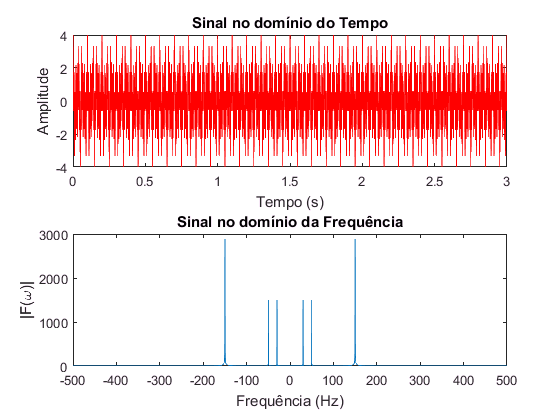

% Calculo do tempo (automático)
t = 0:1/fs:tempo_maximo;

% Sinal desejado
y = cos(2*pi*30*t) + cos(2*pi*50*t) + 2*cos(2*pi*150*t);

%% Plotagem de figura
% No eixo do tempo
subplot(211);        % Subdivisão em 1 
plot(t,y,'r-');      % Plota o sinal com cor vermelha
xlabel('Tempo (s)'); % Legenda do eixo X
ylabel('Amplitude'); % Legenda do eixo Y
title('Sinal no domínio do Tempo');

subplot(212);        % Subdivisão em 2
% Cálculo dos vetores da frequências.
% Pelo teorema de Nyquist, visualizamos até a largura de banda de fs/2
freqx= -fs/2:fs/(length(y)-1):fs/2;                % Dois lados (incluindo o eixo negativo)
% Cálculo da Transformada de Fourier com deslocamento para o centro
freqy = fftshift(fft(y));plot(freqx,abs(freqy));
xlabel('Frequência (Hz)');                         % Legenda X
ylabel('|F(\omega)|');                             % Transformada de Fourier
title('Sinal no domínio da Frequência')

É possível utilizar também as funções prontas listadas abaixo:

%fvtool(y,1,'Fs',fs);                              % Método mais fácil (Filtro passa-tudo = Próprio Sinal)
%freqz(y,1,length(y),fs);                          % Outro método mais fácil